# Actividad 7.1: Presentación

**Paola Rojas Domínguez A01737136**

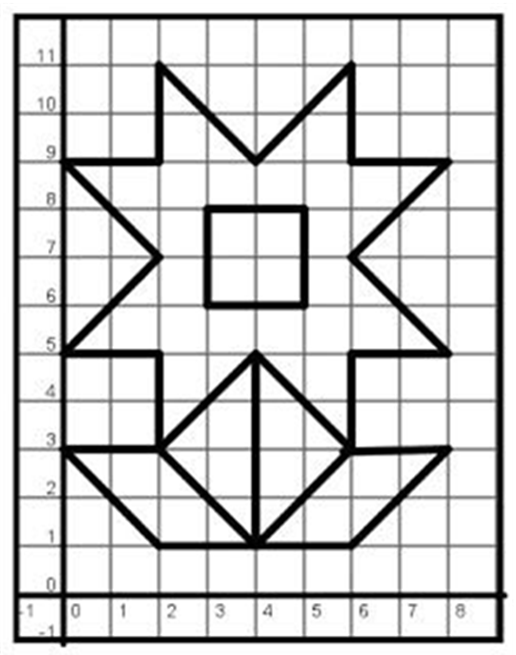

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

## Lazo abierto

### Velocidades de referencia

Se comienza definiendo los vectores de referencia de velocidad.  Esta secuencia está pensada para simular un movimiento cuadrado en el plano.

u = [zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 4*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2.83*ones(1, 10), zeros(1, 10), ones(1, 10), zeros(1, 10), ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 2*ones(1, 10), zeros(1, 10), 1*ones(1, 10)];
w = [0*ones(1, 10), zeros(1, 10), deg2rad(45)*ones(1, 10), zeros(1, 10), deg2rad(135)*ones(1, 10), zeros(1, 10), deg2rad(45)*ones(1, 10), zeros(1, 10), deg2rad(-90)*ones(1, 10), zeros(1, 10), deg2rad(45)*ones(1, 10), zeros(1, 10), deg2rad(135)*ones(1, 10), zeros(1, 10), deg2rad(45)*ones(1, 10), zeros(1, 10), deg2rad(90)*ones(1, 10), zeros(1, 10), deg2rad(135)*ones(1, 10), zeros(1, 10), deg2rad(-135)*ones(1, 10), zeros(1, 10), deg2rad(90)*ones(1, 10), zeros(1, 10), deg2rad(-135)*ones(1, 10), zeros(1, 10), deg2rad(90)*ones(1, 10), zeros(1, 10), deg2rad(-135)*ones(1, 10), zeros(1, 10), deg2rad(90)*ones(1, 10), zeros(1, 10), deg2rad(-135)*ones(1, 10), zeros(1, 10), deg2rad(90)*ones(1, 10), zeros(1, 10), deg2rad(-135)*ones(1, 10), zeros(1, 10), deg2rad(90)*ones(1, 10), zeros(1, 10), deg2rad(-135)*ones(1, 10), zeros(1, 10), deg2rad(90)*ones(1, 10), zeros(1, 10), deg2rad(-135)*ones(1, 10), zeros(1, 10), deg2rad(90)*ones(1, 10), zeros(1, 10), deg2rad(-135)*ones(1, 10), zeros(1, 10), deg2rad(-45)*ones(1, 10), zeros(1, 10), deg2rad(90)*ones(1, 10), zeros(1, 10), deg2rad(-90)*ones(1, 10), zeros(1, 10), deg2rad(-90)*ones(1, 10), zeros(1, 10), deg2rad(-90)*ones(1, 10), zeros(1, 10), deg2rad(-90)*ones(1, 10), zeros(1, 10)];

### Tiempo

A continuación, se establecen los parámetros temporales. El número de muestras `N` se obtiene a partir de la longitud del vector `u`, mientras que el tiempo de muestreo se define como `ts = 0.1` segundos. El vector de tiempo `t` se genera con una distribución lineal.

N = length(u);
tf = N*2;
ts = 0.1;
t = linspace(0, ts, N);

### Condiciones iniciales

Las condiciones iniciales del robot se fijan en el origen del plano, con orientación cero. Los vectores `x1`, `y1` y `phi` representan respectivamente la posición en el eje X, el eje Y y la orientación del robot a lo largo de toda la simulación.

x1 = zeros (1,N+1);
y1 = zeros (1,N+1);
phi = zeros(1, N+1);

Se establece la coordenada inicial, asignando los valores explícitamente en la primera posición de cada vector. 

x1(1) = 4;
y1(1) = 1;
phi(1) = 0;

### Punto de control

También se inicializan los vectores `hx` y `hy` que almacenarán la trayectoria del punto de control del robot (que coincide con el centro del eje entre ruedas), comenzando en la misma posición inicial del robot.

hx = zeros(1, N+1);
hy = zeros(1, N+1);

hx(1) = x1(1);
hy(1) = y1(1);

### Bucle de simulación

El bucle `for` que recorre todas las muestras temporales. En cada iteración, se actualiza la orientación `phi` del robot utilizando integración numérica con el método de Euler. Luego, se calculan las componentes de la velocidad en los ejes X y Y considerando la orientación recién calculada. Con esas velocidades, también mediante Euler, se actualiza la posición del robot. Finalmente, se actualiza la trayectoria del punto de control con las nuevas coordenadas del centro del robot.

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### **a) Configuracion de escena**

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-1 12 -1 12 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

#### **b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;

#### **c) Graficar Trayectorias**

H2=plot3(hx(1),hy(1),0,'c','lineWidth',2);

#### **d) Bucle de simulacion de movimiento del robot**

Se dibuja el robot en su posición inicial mediante una función externa (`MobilePlot_4`) que toma como parámetros la posición, orientación y una escala de visualización. Luego, se dibuja la primera parte de la trayectoria del punto de control en color rojo. El bucle de simulación gráfica recorre los pasos definidos, actualizando la posición del robot y su trayectoria en cada iteración.

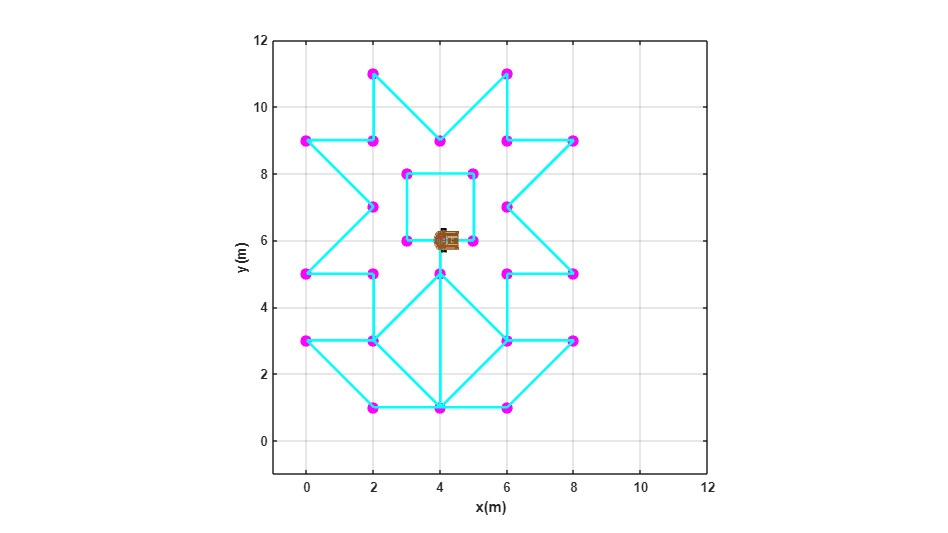

puntosX = [4, 6, 8, 6, 2, 0, 2, 4, 2, 0, 2, 0, 2,  2, 4,  6, 6, 8, 6, 8, 6, 4, 3, 3, 5, 5]; 
puntosY = [1, 1, 3, 3, 3, 3, 1, 5, 5, 5, 7, 9, 9, 11, 9, 11, 9, 9, 7, 5, 5, 6, 6, 8, 8, 6];

% Dibujar puntos fijos en la escena
plot3(puntosX, puntosY, zeros(size(puntosX)), 'mo', 'MarkerSize', 8, 'MarkerFaceColor', 'm');

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'c','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se muestran las gráficas de las velocidades `u` y `w` a lo largo del tiempo. Se usan subplots para presentar ambas curvas por separado, manteniendo una línea clara y visible. Estas gráficas permiten verificar que las referencias de velocidad se aplicaron correctamente a lo largo de la simulación.

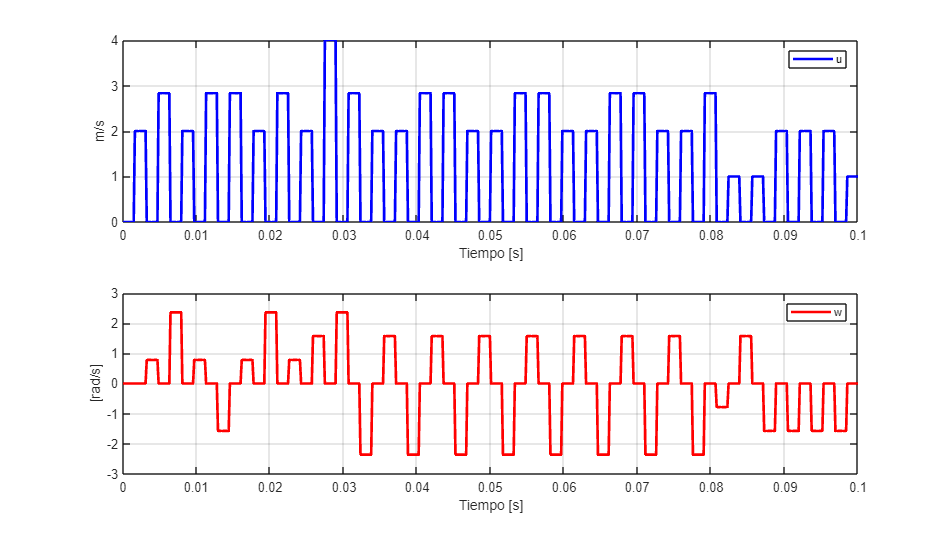

graph=figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

## **Lazo cerrado con posiciones deseadas**

### Tiempo

A continuación, se establecen los parámetros temporales

ts = 0.1;
t_segmento = 15;
N = t_segmento / ts;
t = linspace(0, ts, N);

### Lista de puntos deseados

Se establece una matriz con las coordenadas a las cuales se desea que llegue el robot

puntos_deseados = [6,1; 8,3; 6,3; 4,1; 2,3; 0,3; 2,1; 4,1; 4,5; 2,3; 2,5; 0,5; 2,7; 0,9; 2,9; 2,11; 4,9; 6,11; 6,9; 8,9; 6,7; 8,5; 6,5; 6,3; 4,5; 4,6; 3,6; 3,8; 5,8; 5,6; 4,6];

### Condiciones iniciales

Se establece la coordenada inicial, asignando los valores explícitamente en la primera posición de cada vector. 

x1(1) = 4; 
y1(1) = 1;
phi(1) = 0;

### Punto de control

También se inicializan los vectores `hx` y `hy` que almacenarán la trayectoria del punto de control del robot (que coincide con el centro del eje entre ruedas), comenzando en la misma posición inicial del robot.

hx(1) = x1(1);
hy(1) = y1(1);

scale = 4;

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

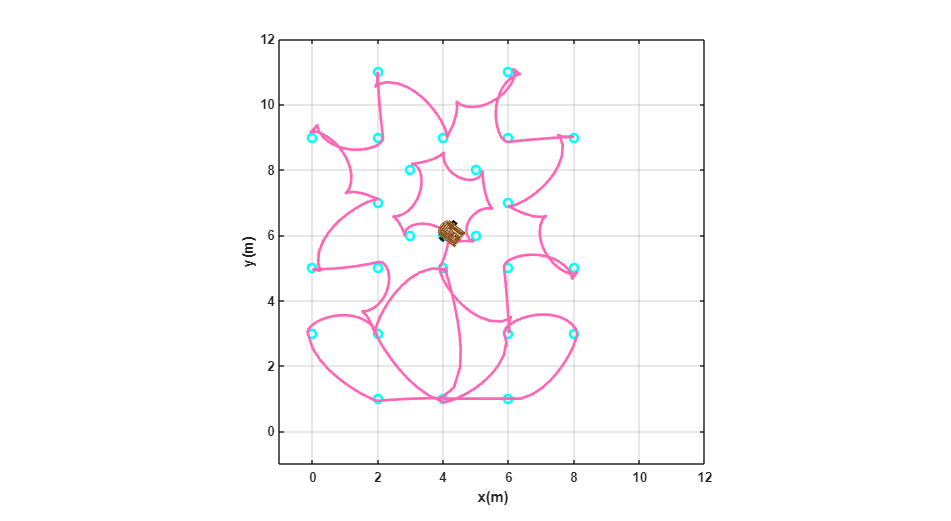

sizeScreen = get(0,'ScreenSize');
scene = figure('Name','Animación trayectoria completa');
set(scene, 'Color','white', 'position', sizeScreen);
set(gca,'FontWeight','bold');
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([-0.1 90]);
axis([-1 12 -1 12 0 1]);

% Inicializar trazado
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'Color', [1 0.4 0.7], 'LineWidth', 2);
plot3(x1(1), y1(1), 0, 'go', 'LineWidth', 2); % punto inicial


% Inicialización para cada segmento
    v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);

for i = 1:size(puntos_deseados,1)
    hxd = puntos_deseados(i,1);
    hyd = puntos_deseados(i,2);

    for k = 1:N
        
        hxe = hxd - hx(end);
        hye = hyd - hy(end);
        he = [hxe; hye];
        Error(k) = norm(he);
        
        J = [cos(phi(end)) -sin(phi(end)); sin(phi(end)) cos(phi(end))];

        Kp_base = 0.5;
        Kp_max = 2;
        Error_max = 2.0;
        error_norm = norm(he);
        Kp_k = Kp_base + (Kp_max - Kp_base) * tanh(error_norm/Error_max);
        K = Kp_k * eye(2);
        
        qpRef = pinv(J) * K * he;
        v(k) = qpRef(1);
        w(k) = qpRef(2);
        
        % Actualizar estado
        phi(end+1) = phi(end) + w(k)*ts;
        xp1 = v(k)*cos(phi(end-1));
        yp1 = v(k)*sin(phi(end-1));
        x1(end+1) = x1(end) + xp1*ts;
        y1(end+1) = y1(end) + yp1*ts;
        hx(end+1) = x1(end);
        hy(end+1) = y1(end);
    end

    % Actualizar animación del movimiento
    step = 1;
    for k = length(hx)-N+1:step:length(hx)
        delete(H1);
        delete(H2);
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
        H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'Color', [1 0.4 0.7], 'LineWidth', 2);
        plot3(hxd, hyd, 0, 'co', 'LineWidth', 2); % punto objetivo
        pause(ts);
    end
end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

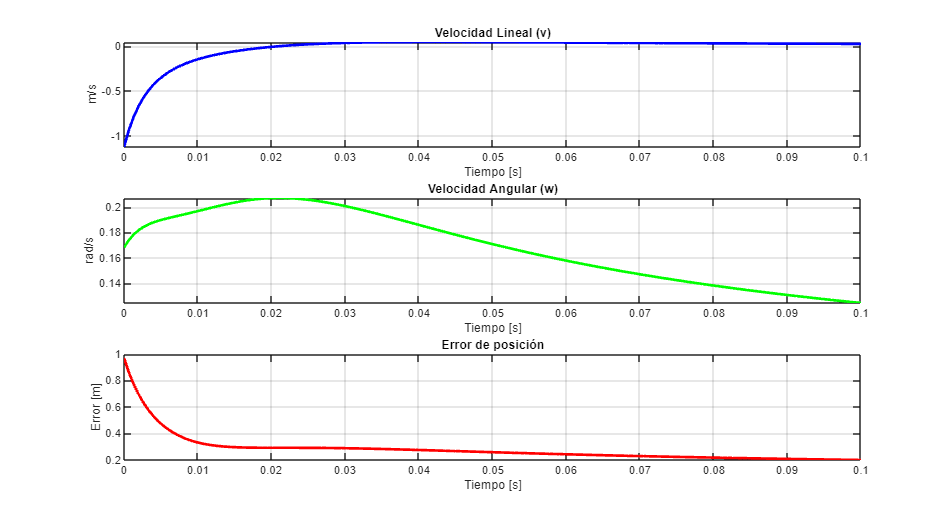

graph = figure('Name',['Gráficas punto ' char(96+i)], 'position', sizeScreen);

subplot(311)
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('m/s');                                                                                                                                                                                                                                                                                                                                                          
title('Velocidad Lineal (v)');

subplot(312)
plot(t, w, 'g', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('rad/s');
title('Velocidad Angular (w)');

subplot(313)
plot(t, Error, 'r', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de posición');

## **Lazo cerrado con posiciones y velocidades deseadas**

### Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=60;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

x1(1)=4;  %Posición inicial eje x
y1(1)=1;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

### Trayectoria Deseada

Ecuaciones paramétricas de la trayectoria deseada

puntos_deseados = [4, 6, 8, 6, 4, 2, 0, 2, 4, 4, 2, 2, 0, 2, 0, 2,  2, 4,  6, 6, 8, 6, 8, 6, 6, 4, 4, 3, 3, 5, 5, 4, 4;
                   1, 1, 3, 3, 1, 3, 3, 1, 1, 5, 3, 5, 5, 7, 9, 9, 11, 9, 11, 9, 9, 7, 5, 5, 3, 5, 6, 6, 8, 8, 6, 6, 5];

tiempos_puntos = linspace(0, tf, size(puntos_deseados, 2));

hxd = interp1(tiempos_puntos, puntos_deseados(1,:), t);
hyd = interp1(tiempos_puntos, puntos_deseados(2,:), t);

%Velocidades de la trayectoria deseada
hxdp = diff(hxd) / ts;
hydp = diff(hyd) / ts;

% Para que hxdp y hydp tengan la misma longitud que t, añadimos el último valor
hxdp = [hxdp, hxdp(end)];
hydp = [hydp, hydp(end)];

### Control, bucle de simulación

Se implementa un bucle `for` que recorre todos los instantes de tiempo definidos en el vector `t`. Dentro de este ciclo, se realiza el cálculo de errores de posición, la matriz Jacobiana, las ganancias, y la ley de control para determinar las velocidades lineal y angular requeridas para que el robot siga la trayectoria deseada.

for k=1:N

#### a) Errores de control

 Se calculan los errores de posición entre la trayectoria deseada y la actual.

    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

#### b) Matriz Jacobiana

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

    J=[cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

#### c) Matriz de Ganancias

Se define una ganancia proporcional para corregir el error.

    K=[0.8 0; 0 0.8];

####  d) Velocidades deseadas

 Se obtienen las velocidades de la trayectoria de referencia.

    hdp=[hxdp(k);hydp(k)];

#### e) Ley de Control

 Calcula las velocidades de referencia para el robot, corrigiendo el error e incorporando la velocidad deseada.

    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 

#### Aplicación de Control al Robot

Una vez calculadas las velocidades de control, se aplican al modelo cinemático del robot mediante integración numérica (Método de Euler) para actualizar su posición y orientación en cada instante de tiempo.

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-1 12 -1 12 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

**b) Graficar robots en la posicion inicial**

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

**c) Graficar trayectorias**

H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'c','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial

**d) Bucle de simulacion de movimiento del robot**

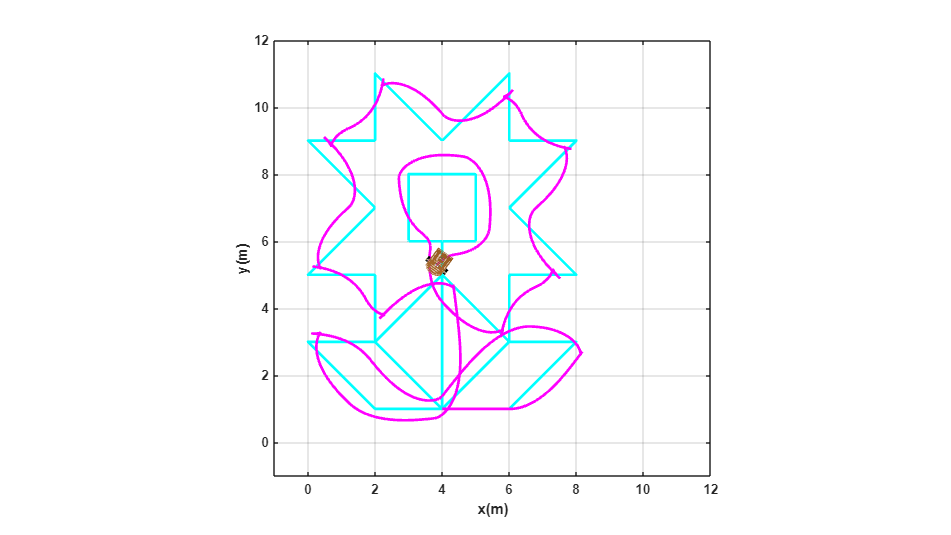

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'m','lineWidth',2);
    
    pause(ts);

end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

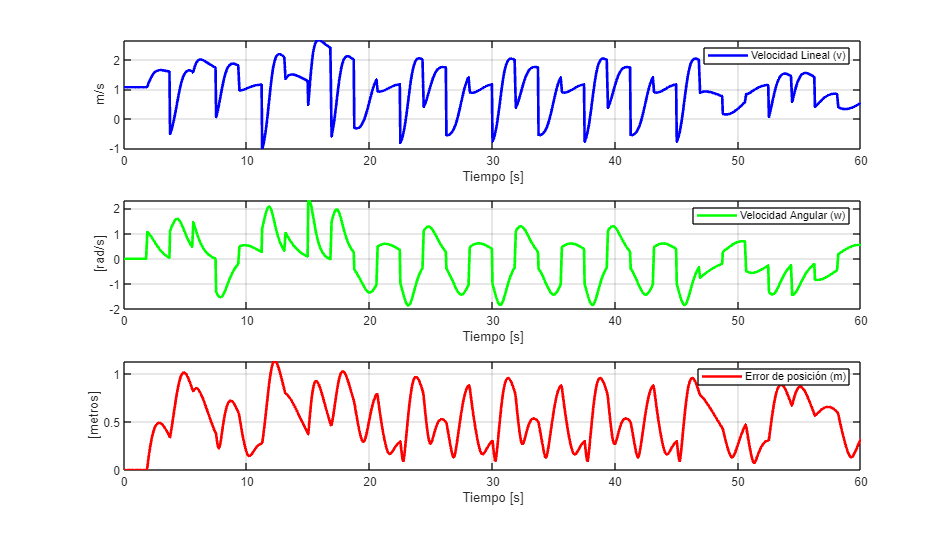

graph=figure;  % Crear figura
set(graph,'position',sizeScreen); % Configurar tamaño de la figura
subplot(311)
plot(t(1:N),v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:N),w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:N),Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

## Seguimiento de waypoints

### Define Vehicle

R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;            
tVec = 0:sampleTime:75;

initPose = [4;1;0];             
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [4,1; 6,1; 8,3; 6,3; 4,1; 2,3; 0,3; 2,1; 4,1; 4,5; 2,3; 2,5; 0,5; 2,7; 0,9; 2,9; 2,11; 4,9; 6,11; 6,9; 8,9; 6,7; 8,5; 6,5; 6,3; 4,5; 4,6; 3,6; 3,8; 5,8; 5,6; 4,6; 4,5];

### Visualización 2D

Se crea un visualizador en 2D (`Visualizer2D`) para representar el movimiento del robot durante la simulación. Se activa la opción para mostrar los waypoints como referencia.

viz = Visualizer2D;
viz.hasWaypoints = true;

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 3.5;

### Bucle principal de simulación

Se inicia el bucle de simulación. En cada iteración se realiza lo siguiente:

close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

#### **a) Salidas del controlador y velocidades de ruedas**

Se obtienen las velocidades lineal (`vRef`) y angular (`wRef`) del controlador, y luego se convierten a velocidades individuales de las ruedas (`wL`, `wR`) mediante cinemática inversa.

    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);

#### **b) Cinemática directa y velocidades en el mundo**

Se calculan las velocidades reales del cuerpo (`velB`) y se transforman del marco del robot al marco del mundo (`vel`) para actualizar la pose correctamente.

    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

#### **c) Integración de la pose**

Se actualiza la posición y orientación del robot usando integración numérica hacia adelante (método de Euler).

    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

#### **d) Visualización del movimiento**

Se actualiza la escena visual con la nueva pose del robot y se sincroniza con el tiempo real simulado.

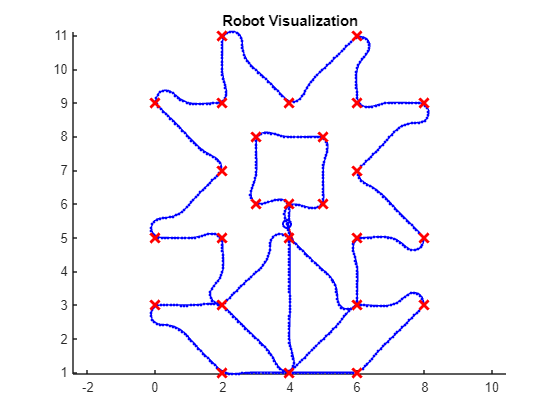

    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end